%file paths of the gauges
path1 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Tokyo III.xlsx";
path2 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Aburatsumo.xlsx";
path3 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Ito II.xlsx";
path4 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Uchiura.xlsx";
path5 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Onisaki.xlsx";
path6 = "C:\Users\ericm\Dropbox\EAS 8803\Project 1\Sensor Data\Osaka.xlsx";

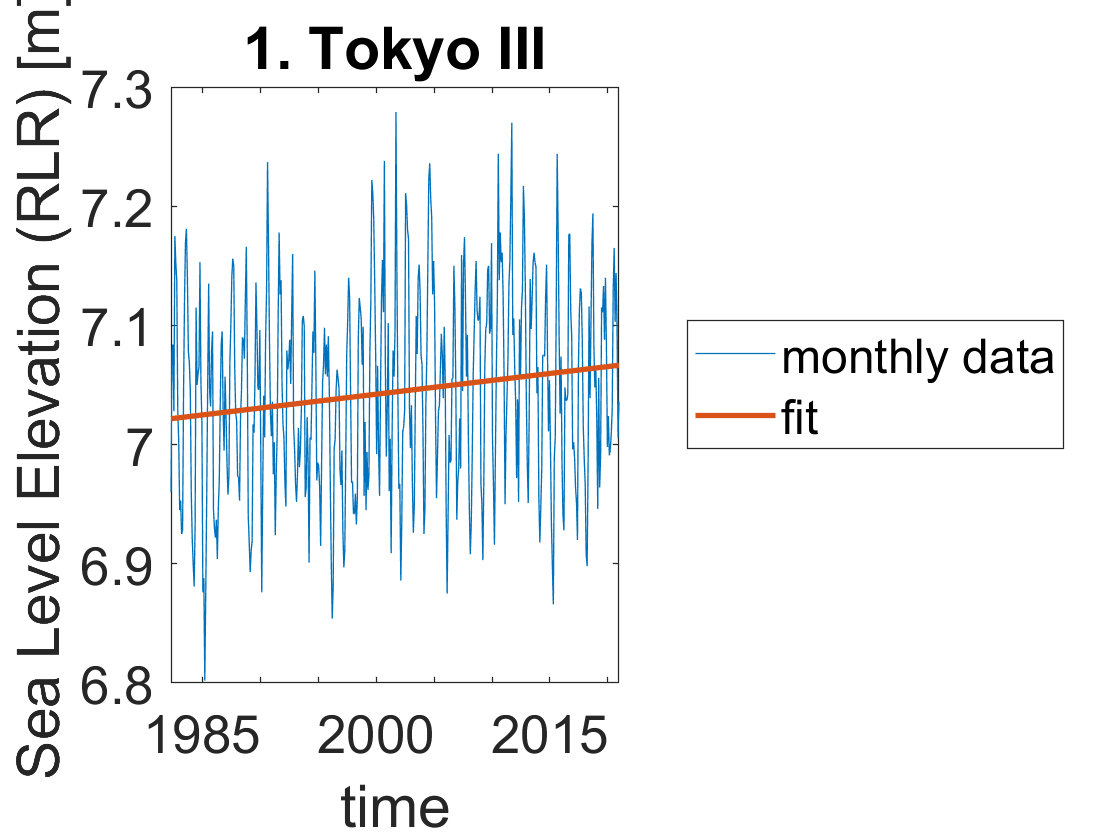

SLR for gauge 1. Tokyo III from 04/16/1982 to 12/15/2020 is 0.11588 cm/y.


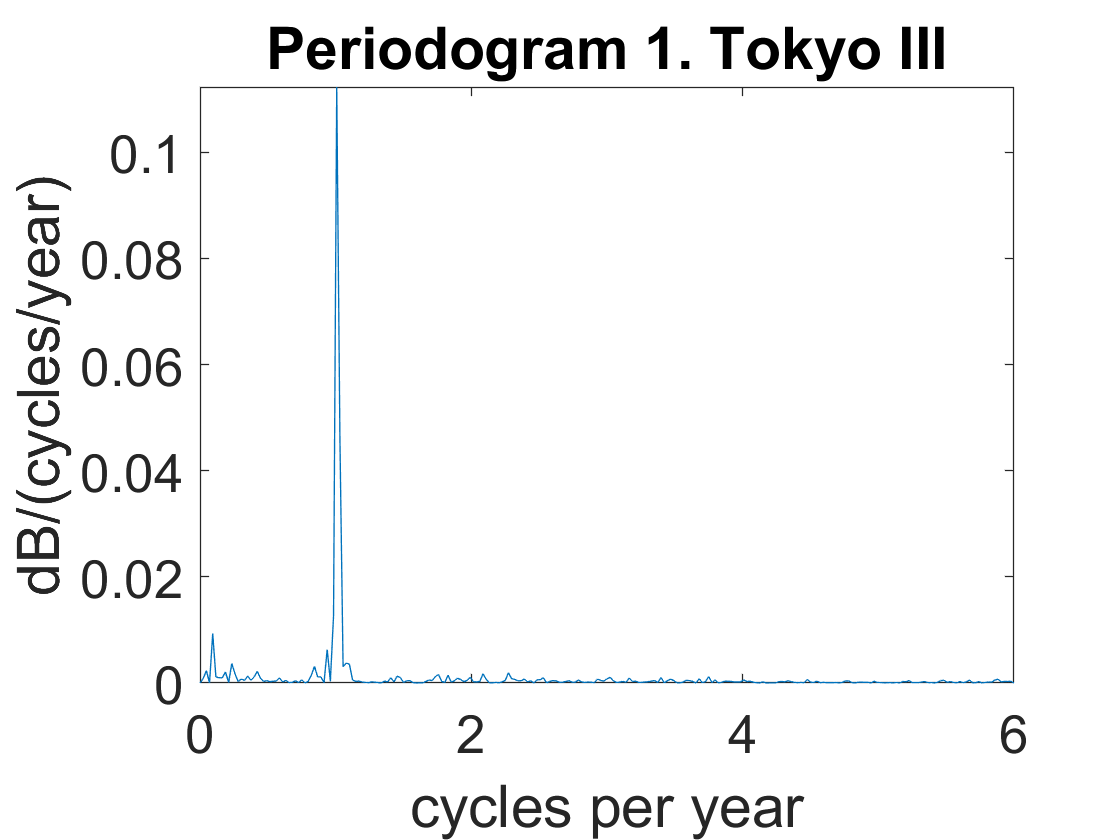

%1. Tokyo III
[date1, SL1] = readGauge(path1);

regsol1 = analyze(date1, SL1, '1. Tokyo III');

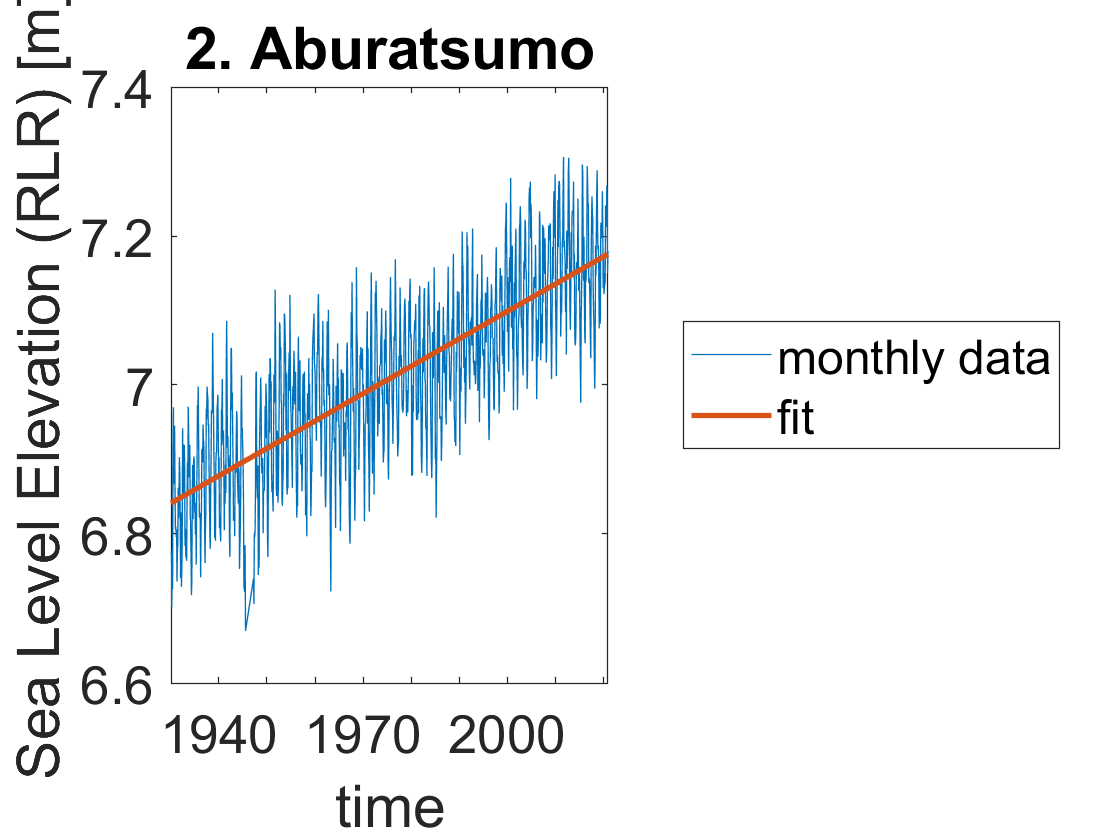

SLR for gauge 2. Aburatsumo from 01/15/1930 to 12/15/2020 is 0.36746 cm/y.


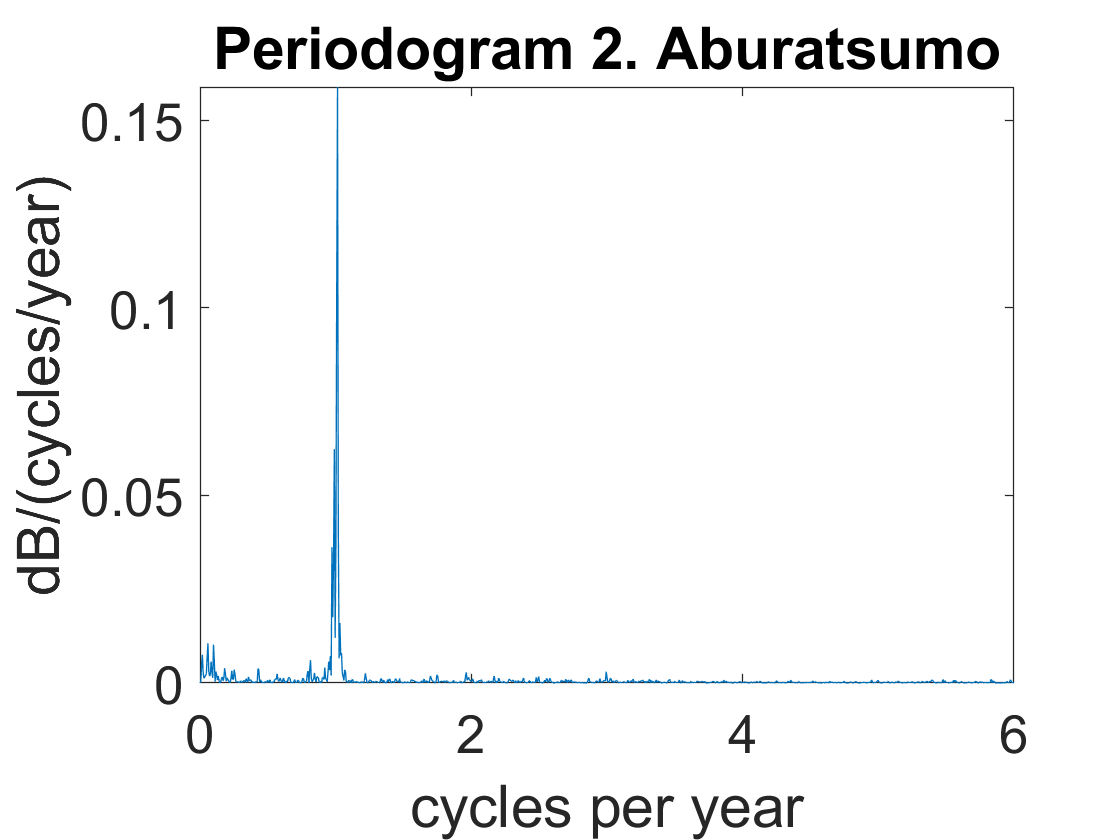

regsol2 =     0.0037
    6.8415


%2. Aburatsumo
[date2, SL2] = readGauge(path2);

regsol2 = analyze(date2, SL2, '2. Aburatsumo');

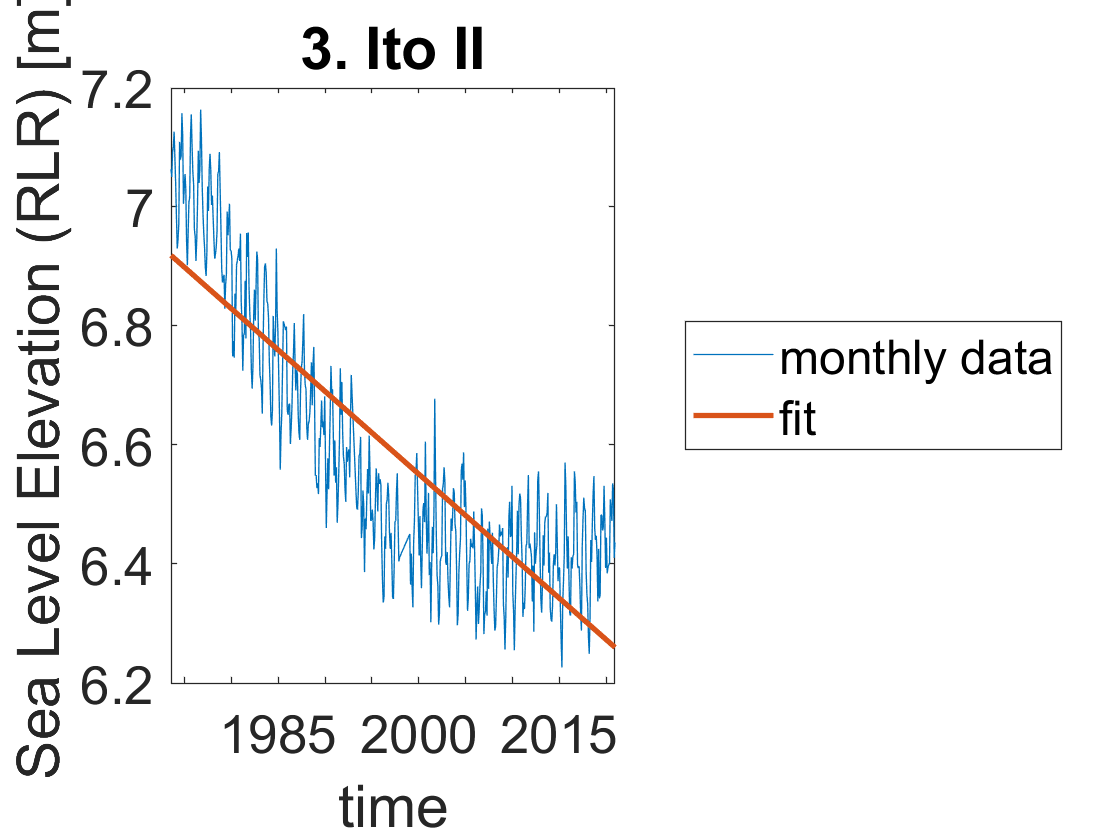

SLR for gauge 3. Ito II from 07/16/1973 to 12/15/2020 is -1.3863 cm/y.


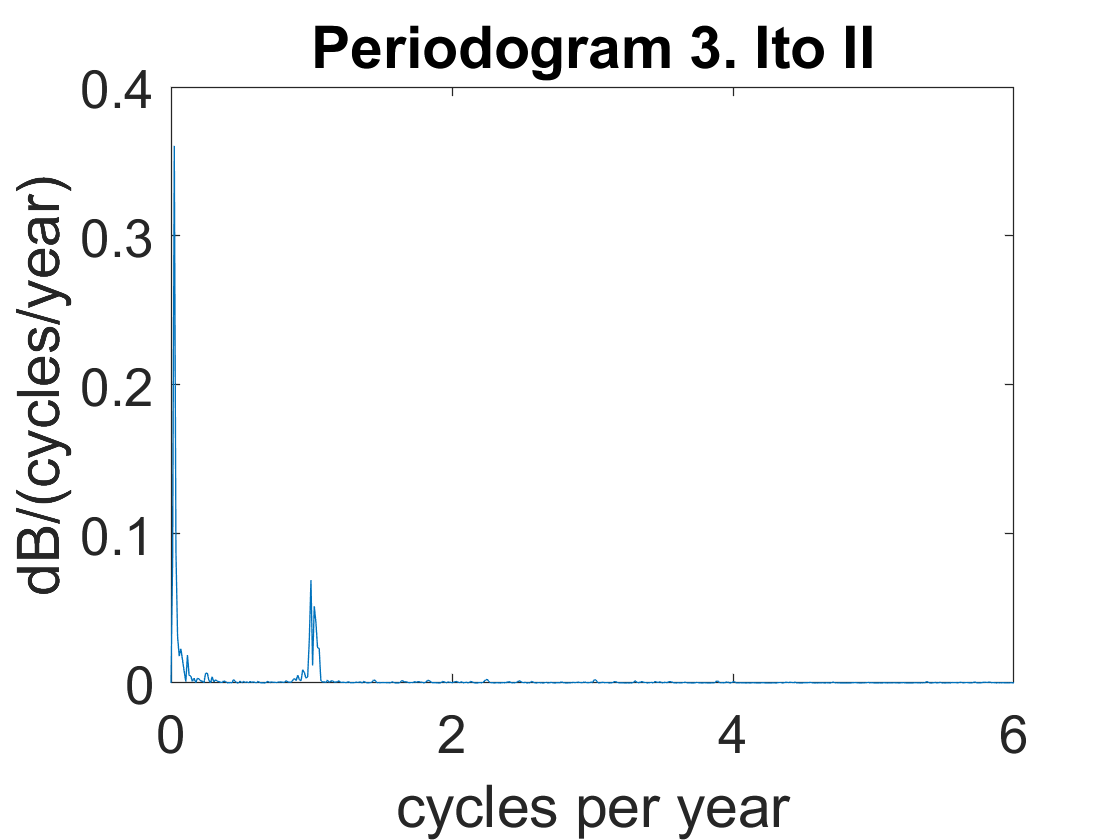

regsol3 =    -0.0139
    6.9175


%3. Ito II
[date3, SL3] = readGauge(path3);

regsol3 = analyze(date3, SL3, '3. Ito II');

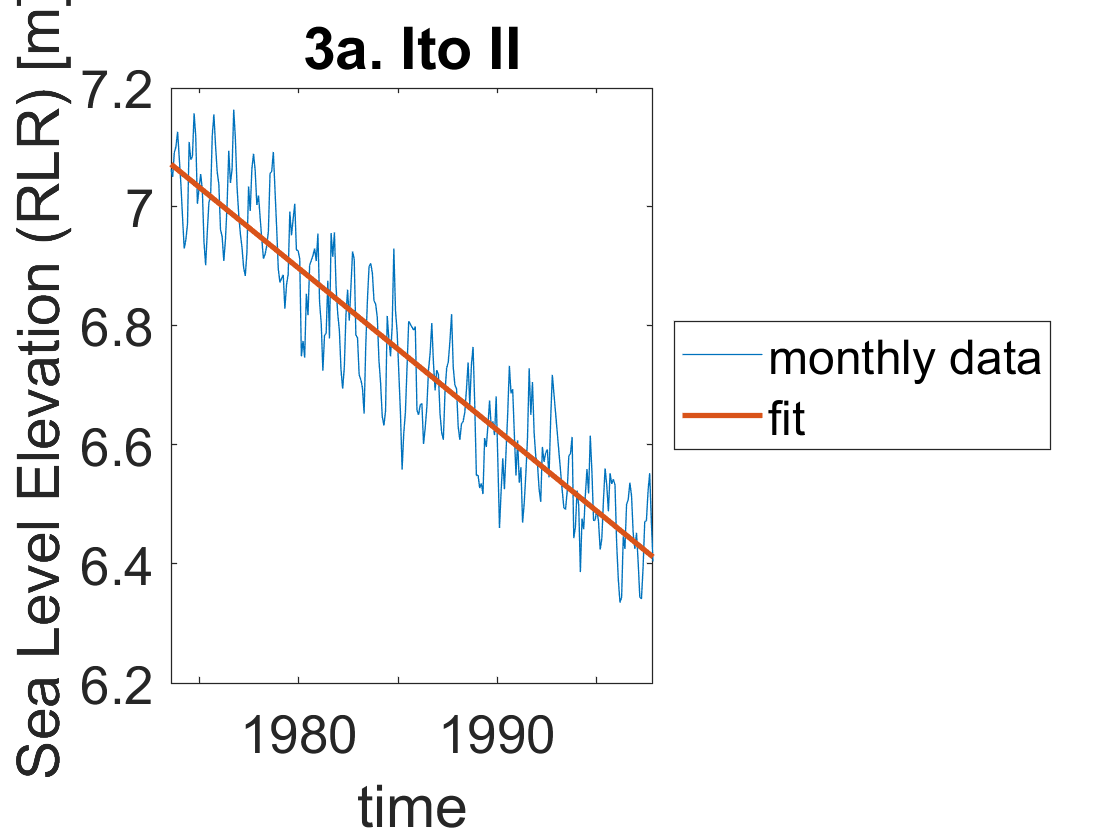

SLR for gauge 3a. Ito II from 07/16/1973 to 11/15/1997 is -2.7062 cm/y.


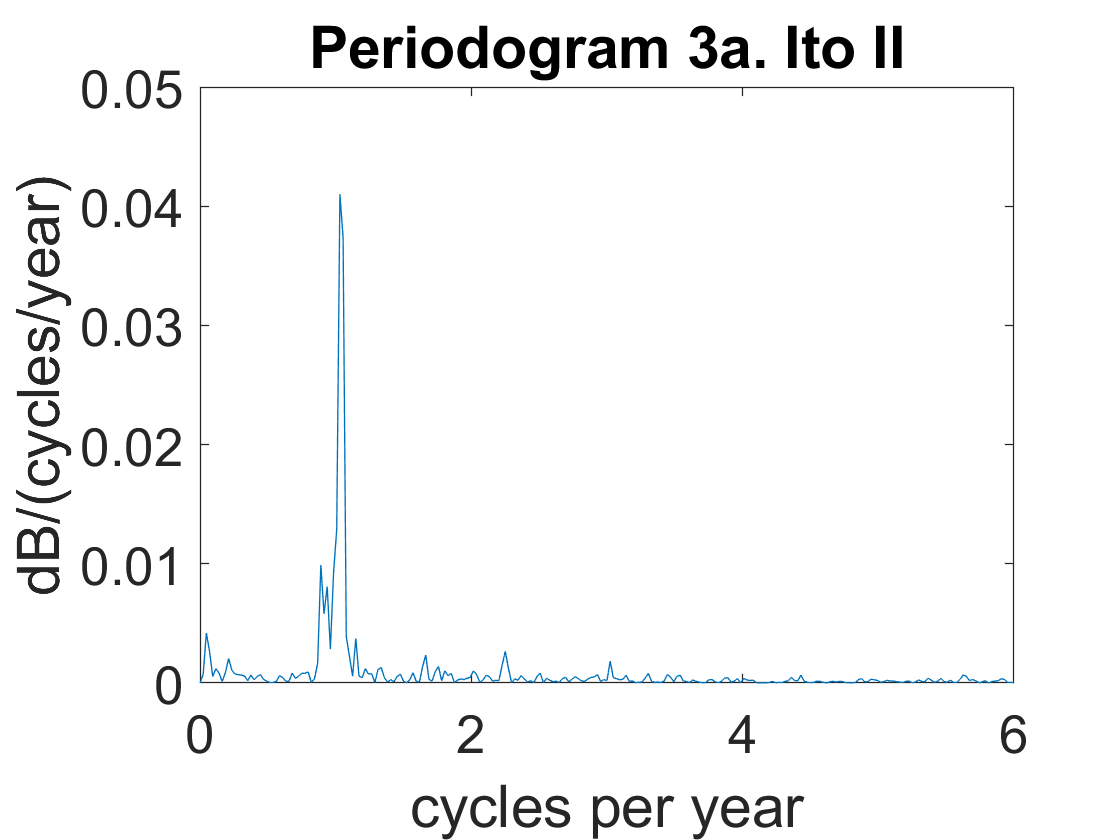

regsol3a =    -0.0271
    7.0705


%%3a. Ito II; 16 Jul 1973 to 15 Dec 1997
[date3a, SL3a, date3b, SL3b] = cleave(date3, SL3, datetime(1997, 12, 15));

regsol3a = analyze(date3a, SL3a, '3a. Ito II');

%%3b. Ito II; 15 Jan 1999 to 15 Dec 2020
%there is a skip between 1997 and 1999

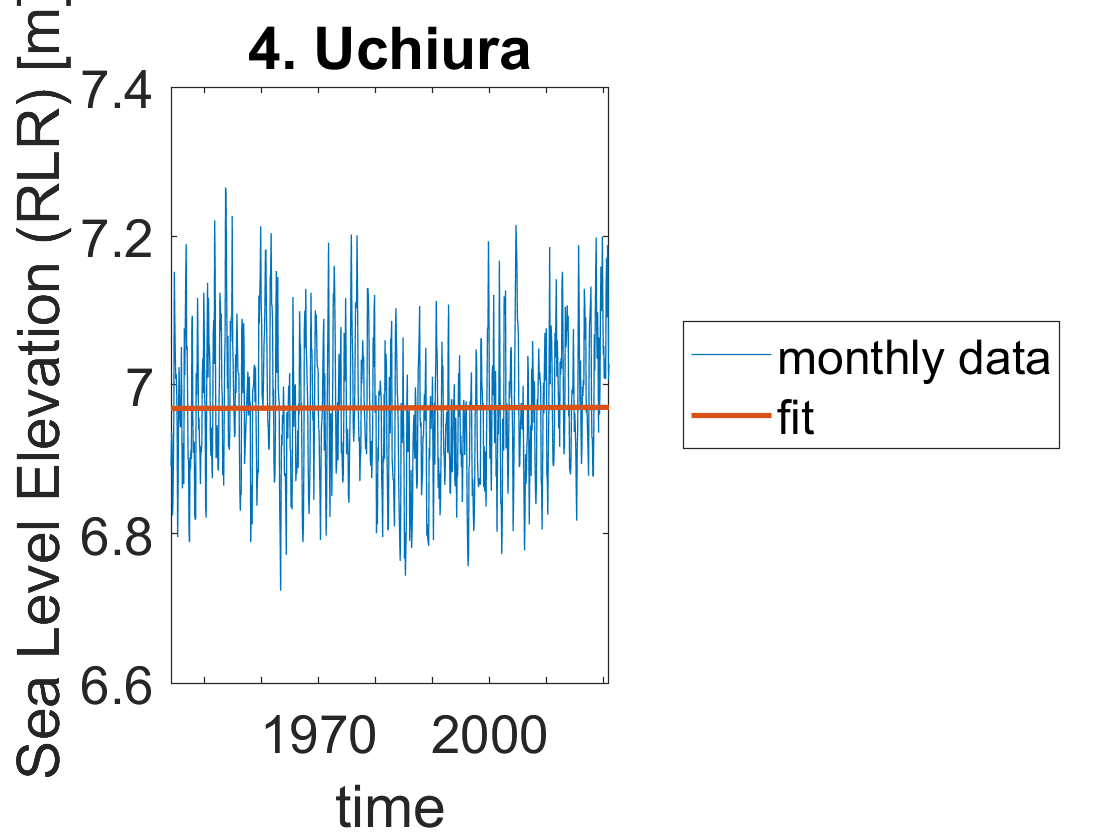

SLR for gauge 4. Uchiura from 01/15/1944 to 12/15/2020 is 0.0018307 cm/y.


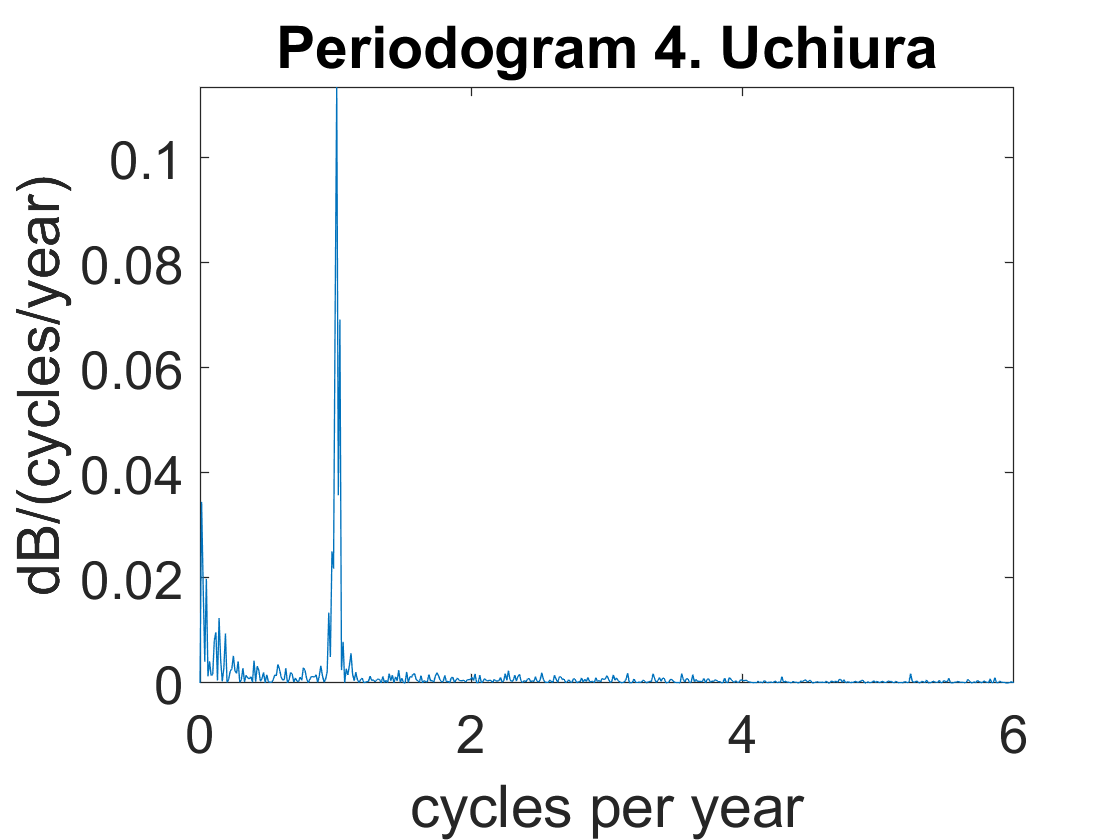

regsol4 =     0.0000
    6.9686


%4. Uchiura
[date4, SL4] = readGauge(path4);

regsol4 = analyze(date4, SL4, '4. Uchiura');

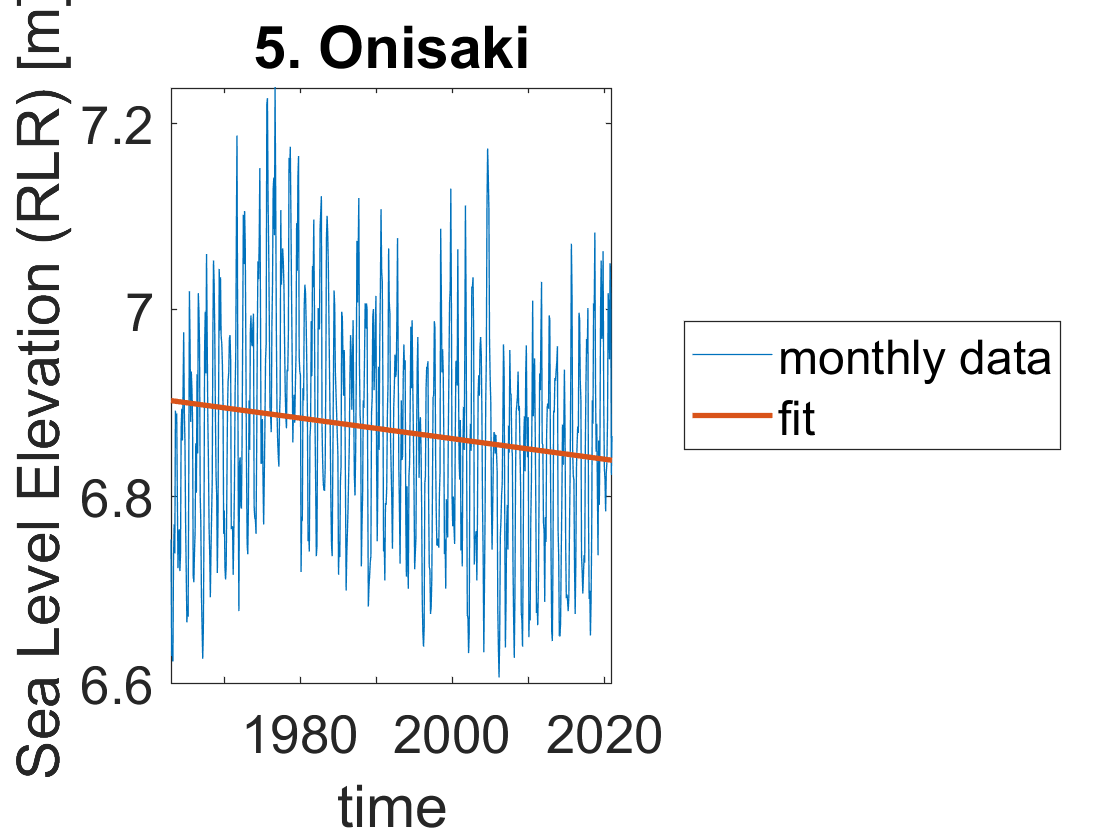

SLR for gauge 5. Onisaki from 01/15/1963 to 12/15/2020 is -0.11031 cm/y.


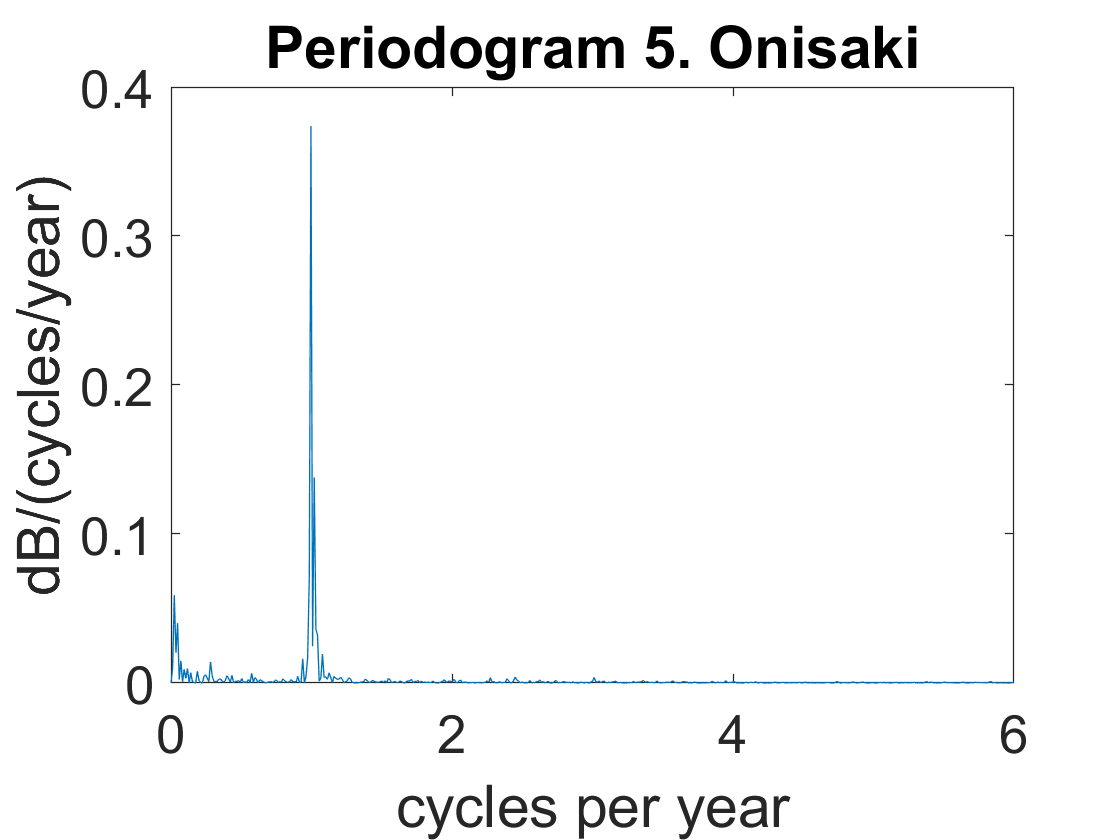

regsol5 =    -0.0011
    6.9028


%5. Onisaki
[date5, SL5] = readGauge(path5);

regsol5 = analyze(date5, SL5, '5. Onisaki');

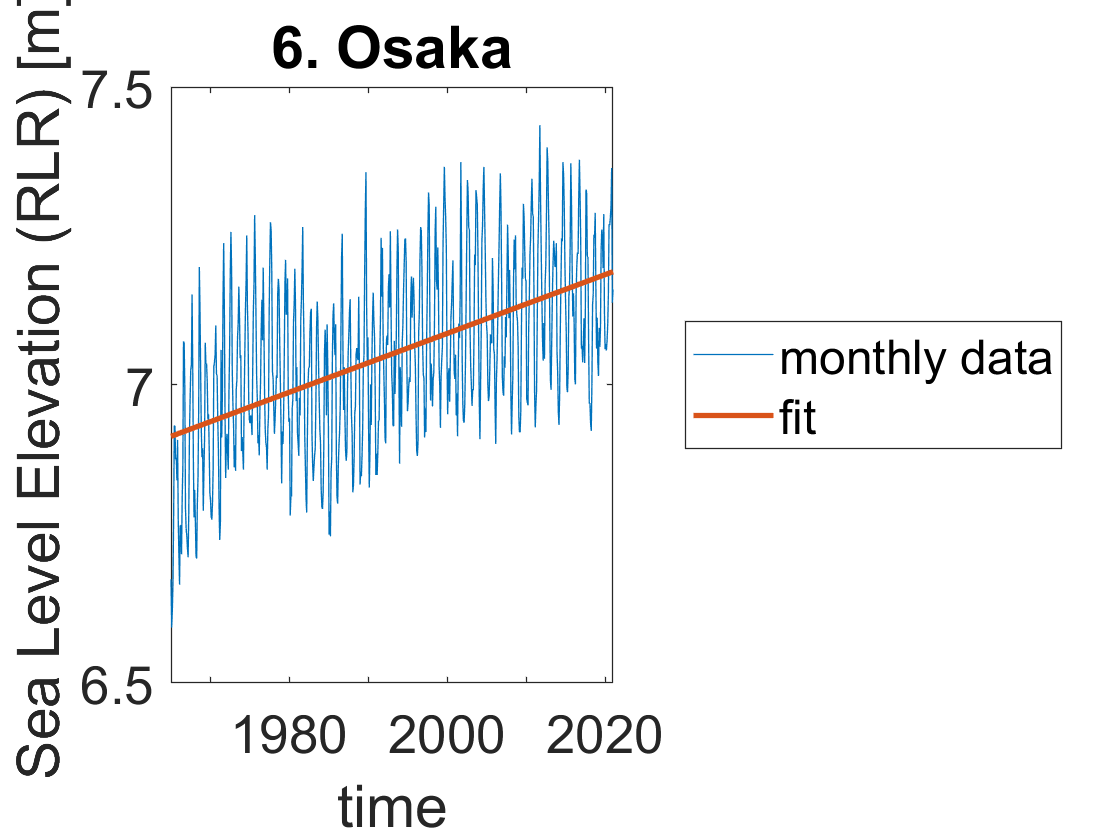

SLR for gauge 6. Osaka from 01/15/1965 to 12/15/2020 is 0.4938 cm/y.


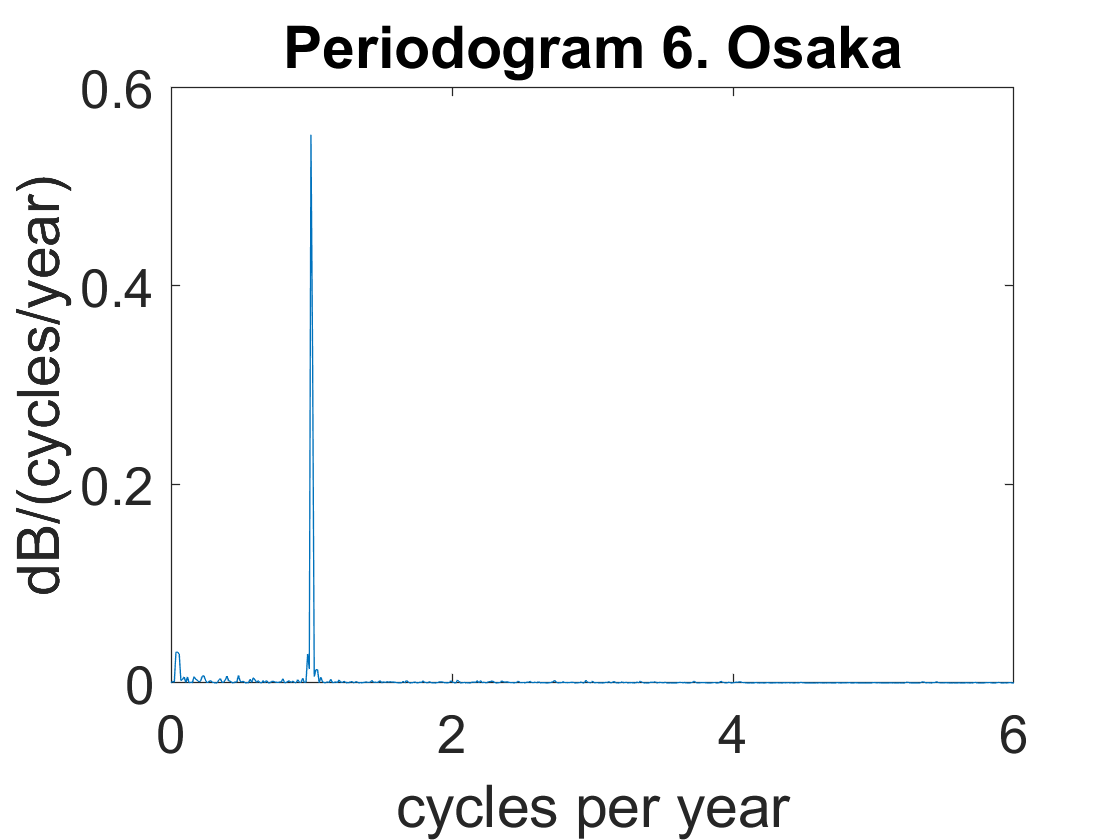

regsol6 =     0.0049
    6.9139


%6. Osaka
[date6, SL6] = readGauge(path6);

regsol6 = analyze(date6, SL6, '6. Osaka');

function [date, SL] = readGauge(path)
%takes data from PSMSL and outputs dates corresponding to SL

%read data
read = readtable(path);
raw = table2array(read);

date = num2cell(ones(size(raw)));
SL = num2cell(ones(size(raw)));

%take out date and SL data
for i = 1:length(raw)
    strings = split(raw{i}, ';');
    date(i) = strings(1);
    SL(i) = strtrim(strings(2));
end

%convert to double
date = str2double(date);
SL = str2double(SL);

%remove null SL
null_ind = SL == -99999;
date(null_ind) = [];
SL(null_ind) = [];

%convert date to datetime
year = floor(date);
secs = (date - year).*(365 + isleapyr(year)).*24.*3600;
date = datetime(year, 1, 0, 0, 0, secs);

%SL to m
SL = SL/1000;
end

function [regsol] = analyze(date, SL, label)
%performs all necessary analysis

%%linear regression
num = datenum(date);
A(:, 1) = (num - num(1))/365;
A(:, 2) = 1;
regsol = A\SL;
linreg = regsol(1).*A(:, 1) + regsol(2);

figure(1)
plot(date, SL)
hold on
plot(date, linreg, 'LineWidth', 2)
set(gca, 'fontsize', 20)
xlabel('time')
ylabel('Sea Level Elevation (RLR) [m]')
title(label)
legend('monthly data', 'fit', 'location', 'eastoutside')
hold off

%slope of regression [cm/y]
out = 'mm/dd/yyyy';
printStr = ['SLR for gauge ', label, ' from ', datestr(date(1), out) ,' to ', datestr(date(end), out), ' is ', num2str(regsol(1)*100), ' cm/y.'];
disp(printStr)

%%periodogram
%normalize data from trend
SL_noSLR = SL - linreg;

%PSD calcs
[pxx, f] = periodogram(SL_noSLR, [], [], 12);

figure(2)
plot(f, pxx)
set(gca, 'fontsize', 20)
title(['Periodogram ' label])
xlabel('cycles per year')
ylabel('dB/(cycles/year)')
end

function [date_beg, SL_beg, date_end, SL_end] = cleave(inDate, inSL, separator)
%returns data from beginning to separator date, inclusive, and the rest
ind = inDate <= separator;

%returns beginning
date_beg = inDate(ind);
SL_beg = inSL(ind);

%returns end
date_end = inDate(~ind);
SL_end = inSL(~ind);
end

function is = isleapyr(yr)
%  returns T for input year being a leapyear
%  dpbozarth       Rev 0   07Jun1998  Initial
%                  Rev 1   31Mar2005  Use eomday() vs number days in year
%                  Rev 2   04Feb2015  Handle new datetime class
if isdatetime(yr), yr=year(yr); end
is=eomday(yr,2)==29;
end